# 2 dimensional Mathieu Equation

We consider two oscillators that are coupled via a nonlinear spring with time varying linear stiffness coefficients.

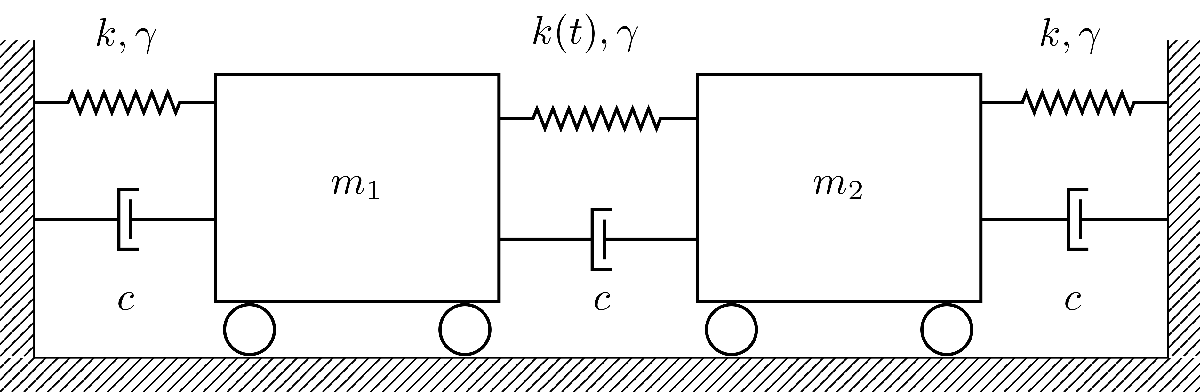

The linear stiffness actuation takes the form $k(t) = k(1+ \epsilon \cos (\Omega t))$

clear all; close all; clc

## Generate model

[M,C,K,fnl,fext] = build_model();

## Dynamical system setup

We consider the parametrically excited system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{g}(\mathbf{x},\dot{\mathbf{x}},\Omega t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{G}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{g}(\mathbf{x, \dot{x}},\phi)\\
\mathbf{0}
\end{array}\right]$$


DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'notation','multiindex')

## Add forcing

The dynamical system is forced parametrically with $\mathbf{g(x},\Omega t) = 
\epsilon\left[\begin{array}{cc} k & -k \\ -k &  k \end{array}\right] \cos(\Omega t) \mathbf{x} 
$.

DS.add_forcing(fext,0.3);

## Linear Modal Analysis 

% Analyse spectrum
[V,D,W_evec] = DS.linear_spectral_analysis();


 The first 4 eigenvalues are given as 
  -0.0250 + 0.9997i
  -0.0250 - 0.9997i
  -0.0750 + 1.7304i
  -0.0750 - 1.7304i



#### Choose Master subspace (perform resonance analysis)

% Set up SSM object
S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','multiindex')

%Choose Master subspace
resModes = [3,4];
S.choose_E(resModes);

sigma_out = 0
sigma_in = 1


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 7; % Approximation order

setup options

outdof = 1;
set(S.Options,    'reltol', 0.5,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7)
set(S.FRCOptions, 'outdof',outdof, 'coordinates','cartesian')
set(S.FRCOptions, 'branchSwitch',true,'periodsRatio',2) %continue BPs of primary branch, 2T response
set(S.contOptions,'PtMX',35,'h_min',1e-4,'h0',1e-4,'bi_direct',false)

choose frequency range around the master mode frequency

omega0 = imag(S.E.spectrum(1));
OmegaRange =[3.35,4.1]  % Subharmonic resonance at Omega = 2 omega_0

OmegaRange =     3.3500    4.1000



epSamp = [0.255, 0.265 , 0.275];


Extract forced response curve

sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 9.04E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.04E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.25E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.53E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 1.90E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 2.36E-02 MB

 Run='SSMsweep0.255.po': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.38e-01  6.97e+00    0.1    0.0    0.0
   1   1  1.00e+00  1.95e-01  0.00e+00  7.12e+00    0.1    0.2    0.0
   2   1  1.00e+00  0.00e+00  0.00e+00  

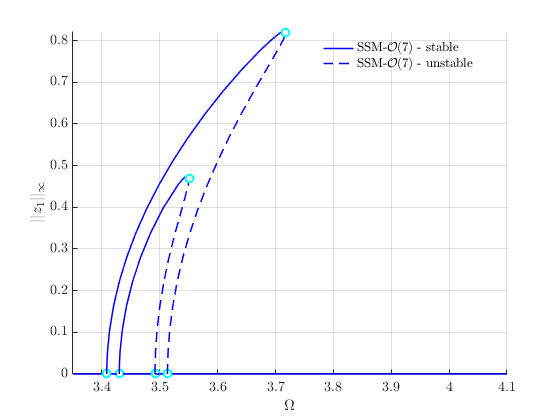

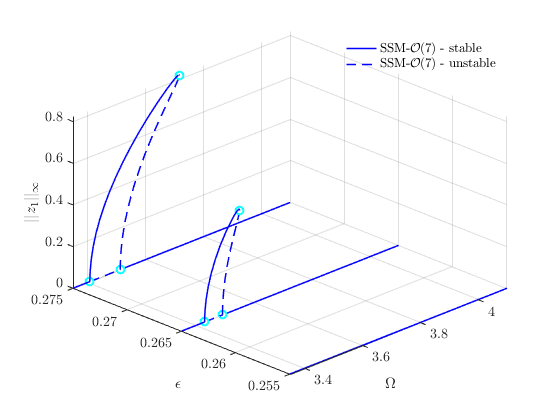

startFRCSSM = tic;

Sweep = S.SSM_poSweeps('SSMsweep',resModes,order,epSamp,OmegaRange);

timings.FRCSSM = toc(startFRCSSM)

timings = struct with fields:
    FRCSSM: 163.4533


figFRC = gcf;

## Get results from full system

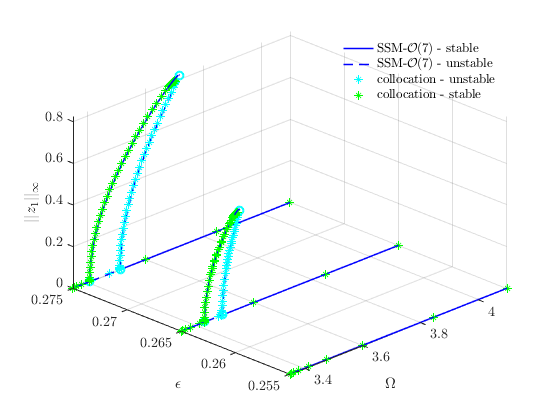


 Run='FRC0.255': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  7.12e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1
    0  00:00:00   7.1170e+00      1  EP      3.3500e+00   3.7512e+00   2.5500e-01   0.0000e+00
    8  00:00:04   7.2438e+00      2  EP      4.1000e+00   3.0650e+00   2.5500e-01   0.0000e+00

 Run='FRC0.265': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  7.12e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1
    0  00:00:00   7.1174e+00      1  EP      3.3500e+00   3.7512e+00   2

nCycles = 10;

coco = cocoWrapper(DS, nCycles, outdof);
set(coco,'initialGuess','forward')
set(coco,'branchSwitch','true','periodsRatio',2) % include new branches, 2T periodic response
set(coco.Options, 'NAdapt', 1);
set(coco.Options,'ItMX',15,'NTST', 30,'PtMX',60,'bi_direct',false,'h0',1e-4); %for convergence, smaller stepsize

figure(figFRC)
hold on
startcoco = tic;
Sweep_coco = coco.coco_poSweeps(epSamp,OmegaRange);

timings.cocoFRC = toc(startcoco)

timings = struct with fields:
     FRCSSM: 163.4533
    cocoFRC: 117.9854


## Stability Diagram from Reduced Dynamics

We extract the stability diagram using continuation of bifurcations. By extending the dynamical system


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi)$$


 to an autonomous system of variables $(\mathbf{z}, \tau) \in \mathbb{R}^N \times S^1$ the trivial fixed point $\mathbf{z} =\mathbf{0}$ of the paremtrically excited system can be interpreted as the periodic orbit $(\mathbf{z}, \tau ) = (\mathbf{0}, t \ \text{mod} \ 2\pi )$ . Any change of the stability behaviour of this periodic orbit is then given by some bifurcation. At the stability boundary of the principal resonance with $\Omega \approx 2 \omega_0$ nontrivial periodic orbits with response period $T = 4 \pi / \Omega$ emerge. If continuation of $2 \pi / \Omega$ periodic orbits is used then these bifurcations show up as period doubling ('PD') bifurcations. Initially continuing $4 \pi / \Omega$ periodic orbits leads to a saddle node ('SN') bifurcation. The function extract_Stability_Diagram allows to chose between these two options for constructing the stability diagram.

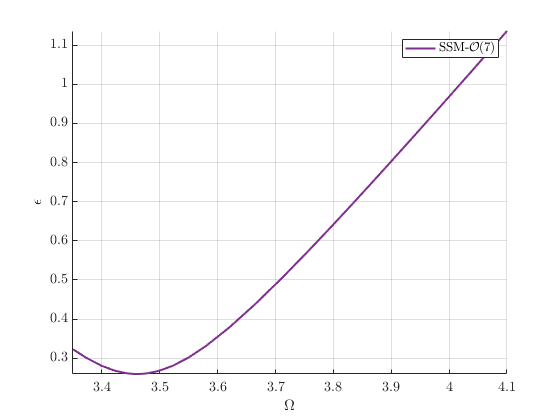

sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 9.04E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.04E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.25E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.53E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 1.90E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 2.36E-02 MB

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  4.31e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
    0  00:00:01   4.3092e+00      1  EP      0.0000e+00   1.8155e+00
   10  00:00:05   4.3098e+00      2      

Total time spent on Stability Diagram computation = 00:01:29


set(S.contOptions,'PtMX',50,'bi_direct',true)
set(S.FRCOptions,'branchSwitch',true)
PlotSD = true;

p0 = [2*omega0,0]; % Initial condition
epRange = [0,1];
figure();
startSDSSM = tic;
SD = S.extract_Stability_Diagram(resModes, order, OmegaRange,epRange,'amp', p0,'PD',PlotSD);

timings.SDSSM = toc(startSDSSM)

timings = struct with fields:
     FRCSSM: 163.4533
    cocoFRC: 117.9854
      SDSSM: 89.7515


figSD = gcf;

## Verification: Collocation using [coco](https://sourceforge.net/p/cocotools/wiki/Home/)

Dankowicz, H., & Schilder, F. (2013).  *Recipes for Continuation,* SIAM Philadelphia. [<https://doi.org/10.1137/1.9781611972573](https://doi.org/10.1137/1.9781611972573)>

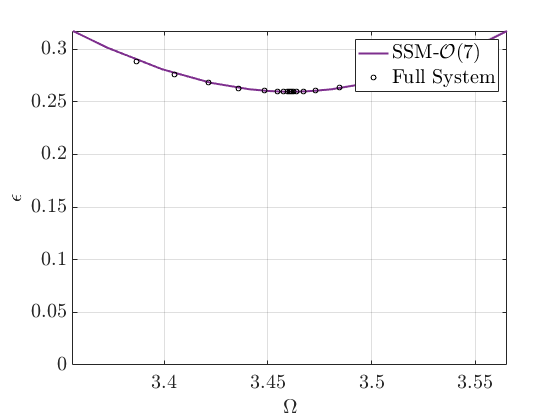


 Run='full_detect_bif': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  6.09e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:00   6.0942e+00      1  EP      0.0000e+00   3.4609e+00
    6  00:00:03   6.1053e+00      2  SN      2.5979e-01   3.4609e+00
    6  00:00:03   6.1053e+00      3  BP      2.5979e-01   3.4609e+00
    8  00:00:04   6.2561e+00      4  EP      1.0000e+00   3.4609e+00

 Run='full_family_bif_1': Continue bifurcations from point 2 in run 'full_detect_bif'.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.48e-07  1.38e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om    po.period      

nCycles = 10;

coco_sd = cocoWrapper(DS, nCycles, []);
set(coco_sd.Options,  'PtMX',10, 'bi_direct',true);
set(coco_sd,'branchSwitch',true)

figure(figSD);
hold on;
startcoco = tic;
SD_full = coco_sd.extract_Stability_Diagram(OmegaRange,epRange,'amp',p0,'SN',PlotSD);

timings.cocoSD = toc(startcoco)

timings = struct with fields:
     FRCSSM: 163.4533
    cocoFRC: 117.9854
      SDSSM: 89.7515
     cocoSD: 22.7492


% plot for paper

MEplotSDintoSweep(figFRC,SD_full,3.8)
xlim([3.39,3.75])
